**Assignment-3a **

`Textbook Problems`

` 1.6 Determine whether or not each of the following signals is periodic: `

`a) `$x_1(t) = 2e^{j(t+\frac{\pi}{4})}u(t)$

`We know that the signal `$u(t)=0 $` for `$\forall \{t<0\}
$`. Which that tell us the signal `$x_1[t]$` can be a value different than zero only for `$t>0$`.`

`For that reason the signal `$x_1(t)$` is not periodic.`

`b) `$x_2[n]=u[n]+u[-n]$` for composite signals, each one has a period N in discrete time singal. `


$$x_2[n] = \begin{array}{cc}
  \{ & 
    \begin{array}{cc}

      1 & n\neq0 \\
      2 & n=0

    \end{array}
\end{array}$$
 

Because of that $x_2[n]$ is not periodic.

`c) `$x_3[n]=\sum_{k=-\infty}^{\infty} \{\delta[n-4k]-\delta[n-1-4k]\}$`. `

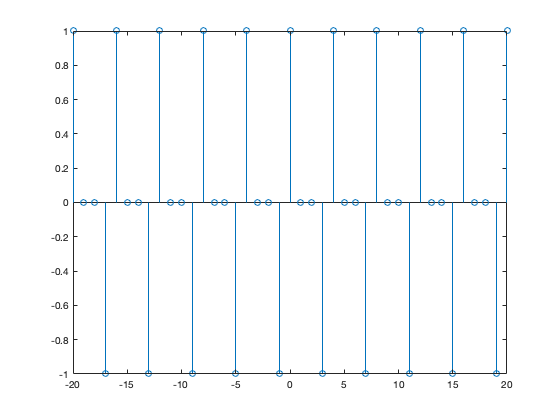

n=[-20:20];
v=0;
for k=n
    v=v+(n==(-4*k))-(n==(-1-4*k));
end
stem(n,v)

`From the plot we can see `$x_3[n]$ is periodic and the period is 3.

`1.16 xConsider a discrete-time system with inout x[n] and output y[n]. The input-output relationshipp for this system is: `$y[n]=x[n]x[n-2]$` . Answer the follwing questions: `

`(a) Is the sysem memoryless? `

`To be memoryless `$y[n]$` should be independent which mean tell us previous or future values cannot effect output but `$y[n]$`, dependent to `$y[n-2]$` because of that it is not memoryless`

`(b) Determine the output of the system when the input is `$A\delta[n]$`, where A is an real or complex number. `

`For the input `$x[n]= A\delta[n]$` :`


$$y[n]=A\delta[n](A\delta[n-2])$$
 
$$ \Longrightarrow y[n]=A^2\delta [n] \delta[n-2]$$
 

`Also we know `$\delta [n]=1 \ when \ n=0$` and similiarly, `$\delta [n-2]=1 \ when \ n=2$` and this implies that,`

$\delta [n] \delta[n-2]=0$`. Therefore, `$y[n]=0$`.`

`(c) Is the system invertible?`

`we know from b) the output, `$y[n]=0$` for that reason,  the system is not invertible.`

`(To be invertible, every input must go different values )`

`1.22 A discrete-time signal is shown in Fighure P1.22. Sketch and label carefully each of the following signals: `

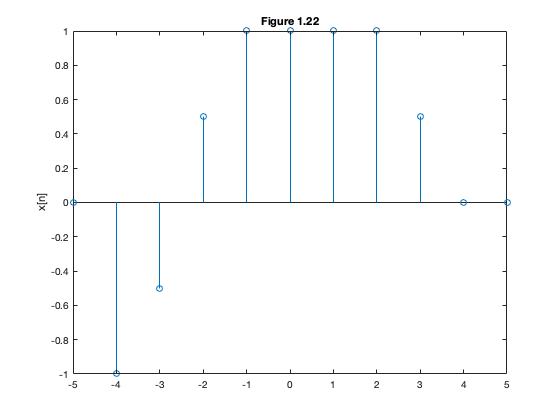

n=[-5:5];
x= n*0;
x(2)=-1;
x(3)=-1/2;
x(4)=1/2;
x(5)=1;
x(6)=1;
x(7)=1;
x(8)=1;
x(9)=1/2;
stem(n,x);
title('Figure 1.22');
ylabel('x[n]');

`(a) x[n-4]`

`The signal shifted to right (delayed) by 4 unit`

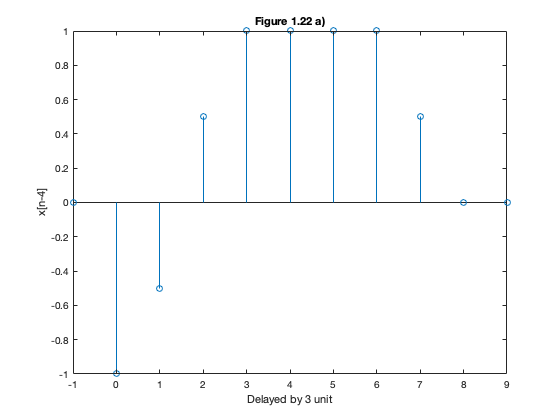

y1=[-1:9];
stem(y1,x)
title('Figure 1.22 a)');
ylabel('x[n-4]');
xlabel('Delayed by 3 unit');

`(b) x[3-n]`

`The signal shifted to left (advanced) by 4 unit`

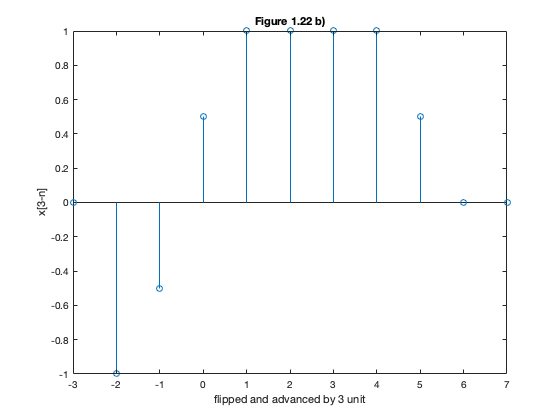

y2n=[-3:7];
y2=x;
len=length(x);
for i=1:len
    y3(i)=x(len+1-i);
end
stem(y2n,y2);
title('Figure 1.22 b)');
ylabel('x[3-n]');
xlabel('flipped and advanced by 3 unit');

`(c) x[3n] `

`The signal is compressed by 3.`

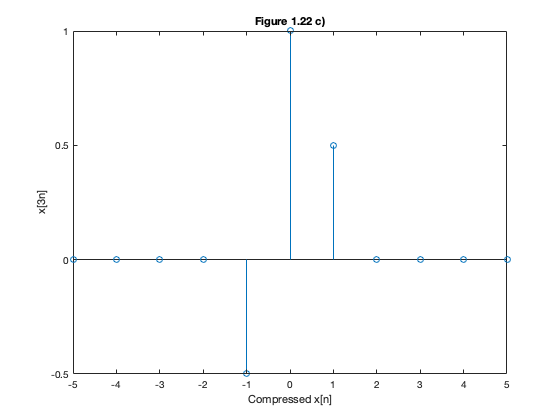

y3=x*0;
y3(5)=-1/2;
y3(6)=1;
y3(7)=1/2;
stem(n,y3);
title('Figure 1.22 c)');
ylabel('x[3n]');
xlabel('Compressed x[n]')

`(e) x[n]u[3-n] `

`The signal `$x[n]u[3-n] $`,is obtained by `$x[n]$` multiplied by `$u[3-n]$ 

%
%       because of the output of u[3-n]= 1 when n = (-infinty,3) 
%
ux=x

ux =          0   -1.0000   -0.5000    0.5000    1.0000    1.0000    1.0000    1.0000    0.5000         0         0


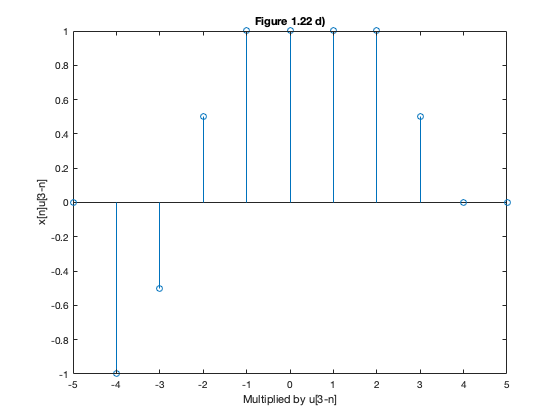

stem(n,ux);
title('Figure 1.22 d)');
ylabel('x[n]u[3-n]');       
xlabel('Multiplied by u[3-n]');

`(f) `$x[n-2]\delta[n-2]$

 `The signal ` $x[n-2]\delta[n-2]$ `is obtained by multiplying with the same impulse (which is 2),`

  $x[n-2] \ and  \  \delta [n-2]$.

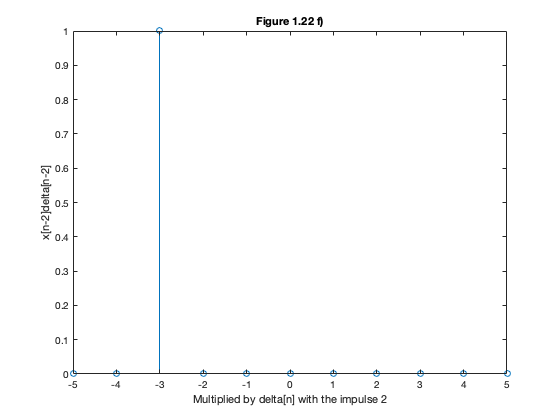

delta= x*0;
% delta[n]= 1, when n = 0
% We delayed the delta and x[n] signals by 2 unit
% delta[n-2]= 1, x[n-1]=1 , when n=2 and in other places the value is 0 
% because of that, for n= 2 the signal 1 other places the signal is 0.
delta(3)=1;
stem(n,delta);
title('Figure 1.22 f)');
ylabel('x[n-2]delta[n-2]');       
xlabel('Multiplied by delta[n] with the impulse 2');

`(g) `$\frac{1}{2}x[n]+\frac{1}{2}(-1)^nx[n]$

`The signal obtained by two different signal by adding `$\frac{1}{2}x[n]$  `and ` $\frac{1}{2}(-1)^nx[n]$.

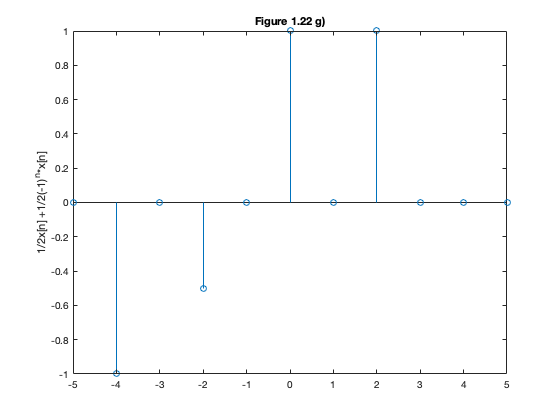

%   n=-4 => 1/2x[n] +1/2(-1)^n*x[n] = x[-4]=-1
%   n=-3 => 1/2x[n] +1/2(-1)^n*x[n] = 0
%   n=-2 => 1/2x[n] +1/2(-1)^n*x[n] = x[-2]=-1/2
%   n=-1 => 1/2x[n] +1/2(-1)^n*x[n] = 0
%   n=0 => 1/2x[n] +1/2(-1)^n*x[n] = x[0]=1
%   n=1 => 1/2x[n] +1/2(-1)^n*x[n] = x[0] 
%   n=2 => 1/2x[n] +1/2(-1)^n*x[n] = x[2]=1
%   n=3 => 1/2x[n] +1/2(-1)^n*x[n] = 0
%   n=4 => 1/2x[n] +1/2(-1)^n*x[n] = 0...

y7= x*0;
y7(2)=-1;
y7(4)=-1/2;
y7(6)=1;
y7(8)=1;
stem(n,y7);
title('Figure 1.22 g)');
ylabel('1/2x[n] +1/2(-1)^n*x[n]');    

`1.27 In this chapter, we introduced a number of general properties of systems. In particular, a system may or may not be `

`1. Memoryless `

`2. Time invariant `

`3. Linear `

`4. Causal `

`5. Stable`

`Determine which of these properties hold and which do not hold. Justify at least one of which properties Does Not hold by a counter example. In each example, y(t) denote the system output and x(t) is the system input. `

`(a) `$y(t)= x(t-2)+x(2-t)$

`Lets consider, the output at `$t=0$`:`

        `The output `$y(0)$`, at `$t=0$, depends on past value, $x(-2)$`, and the future value, `$x(2)$`.`

`    Therefore,according to the definitions of Casuality and Memoryless, the system is not                       `

         `Casual and has Memory.`

`Lets consider, a shift `$t_0 $` in the output` $y(t)$:

            
$$y(t-t_0)=x(t-t_0)+x(2-(t-t_0))$$


            
$$y(t-t_0)=x(t-t_0)+x(2-t+t_0))$$


`If the input is shifted to `$t_0$  a`nd passed through the system, then the output:`

    
$$x(t-t_0) \Longrightarrow y(t)=x(t-t_0)+x(2-t-t_0))$$


`It is clear that a shift of `$t_0$ `in the input doesn't have a responding shift in the output, which implies that the system is Time-Variant.`

`Lets Check linearity:`

    
$$y_1[n]=x_1(t-2)+x_1(2-t)$$


    
$$y_2[n]=x_2(t-2)+x_2(2-t)$$


    `Lets take third input `$x_3(t)$` as linear combination of `$x_1(t) \  and  \ x_2(t)$

                
$$x_3(t)=ax_1(t)+bx_2(t)$$


    `To be linear the output should be `$y_3(t)=ay_1(t)+by_2(t)$.

        
$$y_3(t)=x_3(t-2)+x_3(2-t)$$


        
$$y_3(t)=ax_1(t-2)+bx_2(t-2)+ax_1(2-t)+bx_2(2-t)$$


        
$$y_3(t)=[ax_1(t-2)+ax_1(2-t)]+[bx_2(t-2)+bx_2(2-t)]$$


        
$$y_3(t)=a[x_1(t-2)+x_1(2-t)]+b[x_2(t-2)+x_2(2-t)]$$


        
$$y_3(t)=ay_1(t)+by_2(t)$$


  `For that reason, the system is Linear.`

` Lets consider, `$\mid x(t) \mid < \infty$ , `For all t, then,`

        
$$|y(t)| =|x(t-2)+x(2-t)|$$


        $|y(t)| \leq |x(t-2)|+|x(2-t)|$              `(From triangle inequality)`

        
$$|y(t)| \leq \infty$$


` Because of that, the system is Stable.`

`(b) `$y(t)=cos(3t)t$

`Lets consider the output `$t=t_1$:

        
$$y(t_1)=cos(3(t_1))t_1$$


`The output depends upon current value. Therefore, according to the definions of Causality and Memoryless, the system is Causal and Memoryless.`

`Lets consider, a shift `$t_0 $` in the output` $y(t)$:

            
$$y(t-t_0)=cos(3(t-t_0))x(t-t_0)$$


            
$$y(t-t_0)=cos(3t-3t_0)x(t-t_0)$$


`If the input is shifted to `$t_0$  a`nd passed through the system, then the output:`

    
$$x(t-t_0) \Longrightarrow y(t)=cos(3t)x(t-t_0)$$


`It is clear that a shift of `$t_0$ `in the input doesn't have a responding shift in the output, which implies that the system is Time-Variant.`

`Lets check the linearity of the system:`

        
$$y_1(t)=cos(3t)x_1(t)$$


                 
$$y_2(t)=cos(3t)x_2(t)$$


`Lets consider a third input `$x_3(t)$` as the combination of `$x_1(t) \ and \ x_2(t)$:

                 
$$x_3(t) = ax_1(t)+bx_2(t)$$


`Therfore the output `$y_3(t)$`:`

        
$$y_3(t)=cos(3t)x_3(t)$$


                 
$$y_3(t)=cos(3t)\{  ax_1(t)+bx_2(t)   \}$$


                 
$$y_3(t)= acos(3t)x_1(t)+bcos(3t)x_2(t)$$


                 
$$y_3(t)=ay_1(t)+by_2(t)$$


`That show us, the system is Linear.`

`Lets consider, `$|x(t)| < \infty$ `for all `$t$`:`

        
$$|y(t)| =|cos(3t)x(t)|$$


        
$$|y(t)| =|cos(3t)||x(t)|$$


        $|y(t)|\leq  |x(t)|$                                 `(From triangle inequality)`

        
$$|y(t)| <\infty$$


   `It is clear that, the system is Stable.`

`(c) `$y(t) =\int_{-\infty}^{2t}x(\tau)d\tau$

`Consider, the output at` $t=t_1$`:`

                
$$y(t_1) =\int_{-\infty}^{2t_1}x(\tau)d\tau$$


`The output `$y(t_1) \ at \ t=t_1$`, depends the past value, `$-\infty < t\leq t_1-1$, `present values `$t_1+1 \leq t <2t_1$.

`Therefore, according to the definitions of Causality and Memoryless, the system is not Casual and has Memory.`

`Lets consider, a shift `$t_0 $` in the output` $y(t)$:

            
$$y(t-t_0)= \int_{-\infty}^{2(t-t_0)}x(\tau)d\tau$$


            
$$y (t-t_0) = \int_{-\infty}^{2t-2t_0} x(\tau) d\tau$$


`If the input is shifted to `$t_0$  a`nd passed through the system, then the output:`

    
$$x (t-t_0) = \int_{-\infty}^{2t} x(\tau -t_0) d\tau$$


`It is clear that a shift of `$t_0$ `in the input doesn't have a responding shift in the output, which implies that the system is Time-Variant.`

`Lets check the linearity of the system:`

        
$$y_1 (t) =  \int_{-\infty}^{ 2t}  x_1( \tau )  d\tau$$


                 
$$y_2 (t) =  \int_{-\infty}^{ 2t}  x_2( \tau )  d\tau$$


`Lets consider a third input `$x_3(t)$` as the combination of `$x_1(t) \ and \ x_2(t)$:

                 
$$x_3(t) = ax_1(t)+bx_2(t)$$


`Therfore the output `$y_3(t)$`:`

        
$$y_3 (t) =   \int_{-\infty}^{ 2t}  x_3( \tau )  d\tau$$


                 
$$y_3(t)=y_3 (t) =   \int_{-\infty}^{ 2t}   \{  ax_1(t)+bx_2(t)   \}  d\tau$$


                 
$$y_3(t)=a  \int_{-\infty}^{ 2t}   x_1(\tau)  d\tau +b  \int_{-\infty}^{ 2t}   x_2(t) d\tau$$


                 
$$y_3(t)=ay_1(t)+by_2(t)$$


`That show us, the system is Linear.`

`Lets consider, `$|x(t)| < \infty$ `for all `$t$`:`

        
$$|y(t)| = |  \int_{-\infty}^{ 2t}  x( \tau )  d\tau |$$


`From triangle inequality for integrals, for any function `$f(t)$:

                            
$$ |  \int_{t}  f( \tau )  d\tau | \leq    \int_{t}  f( \tau )  d\tau $$


                            
$$\Longrightarrow |y(t)| \leq  \int_{-\infty}^{ 2t}  x( \tau )  d\tau $$


  Even if $|x(t)|< \infty$`,the integral value depends upon the value of `$t$` and it varies with `$t$.

  The `output is not bounded even if a bounded input applied. Therefore, the system is not Stable.`

`1.31 In this problem, we illustrate one of the most important consequences of the properties of linearity and time invariance. Speciffically, once we know the response of a linear system or a linear timeinvariant (LTI) system to a singal input or the response to several inputs, we directly compute the responses to many other input signals. Much of the remindr of this book deals with a thorough expoitation of this fact in order to develop results and techniques for analyzig and synthesizing LTI systems. `

`(a) Consider an LTI system whose response to the signal `$x_1(t)$` in the Figure P1.31(a) is the signal `$y_1(t)$  `illustrated in Figure P1.31(b). Determine and sketch arefully the response of the system to the input `$x_2(t)$`depicted in Figure P1.3(c). `

`Given an LTI system whose response to an input signal `$x_1(t)$ is $y_1(t)$

                
$$x_1(t) \overset{LTI}{\rightarrow}  y_1(t)$$


`From the input `$x_2(t)$` shows in the Figure, the signal `$x_2(t)$ `can be written in terms of` $x_1(t)$ `as:`

                                         
$$x_2(t)= x(t)-x(t-2)$$


`As it was said that,` $x_1(t)$`is linear and time invariant, the output `$y_2(t)$ `of `$x_2(t)$ `is:`

                 
$$x_2(t)=x_1(t)-x_1(t-2) \overset{LTI}{\rightarrow} y_2(t)=y_1(t)-y_1(t-2)$$


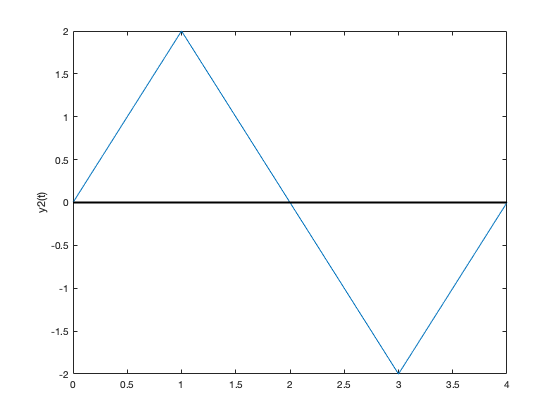

n1=[0:4];
x2=n1*0;
x2(2)=2;
x2(4)=-2;
plot(n1,x2);
ylabel('y2(t)');
line(xlim, [0,0], 'Color', 'black', 'LineWidth', 2);

`(b) Determine and sketch the response of the system consider in part (a) to the input `$x_3(t)$ `shown in Figure P1.31(d).`

`From the input `$x_3(t)$ `shown in Figure P1.31(d), the signal `$x_3(t)$ `can be written in terms of `$x_1(t)$:

                                                                
$$x_3(t)= x(t)+x(t+1)$$


`As it was said that, `$x_1(t)
$ `is LTI, the output `$y_3(t)$ `of the signal `$x_3(t)$ :

                                                
$$x_3(t)= x_1(t)+x_1(t+1) \overset{LTI }{\rightarrow}  y_3(t)= y_1(t)+y_1(t+1)$$


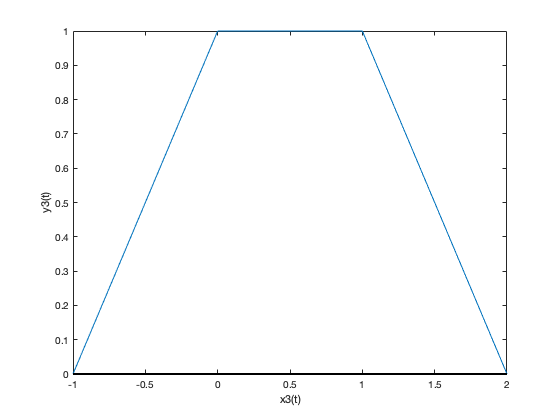


nb=[-1:2];
xb=[0,1,1,0];
plot(nb,xb);
ylabel('y3(t)');
xlabel('x3(t)');
line(xlim, [0,0], 'Color', 'black', 'LineWidth', 2);